Question 5.1

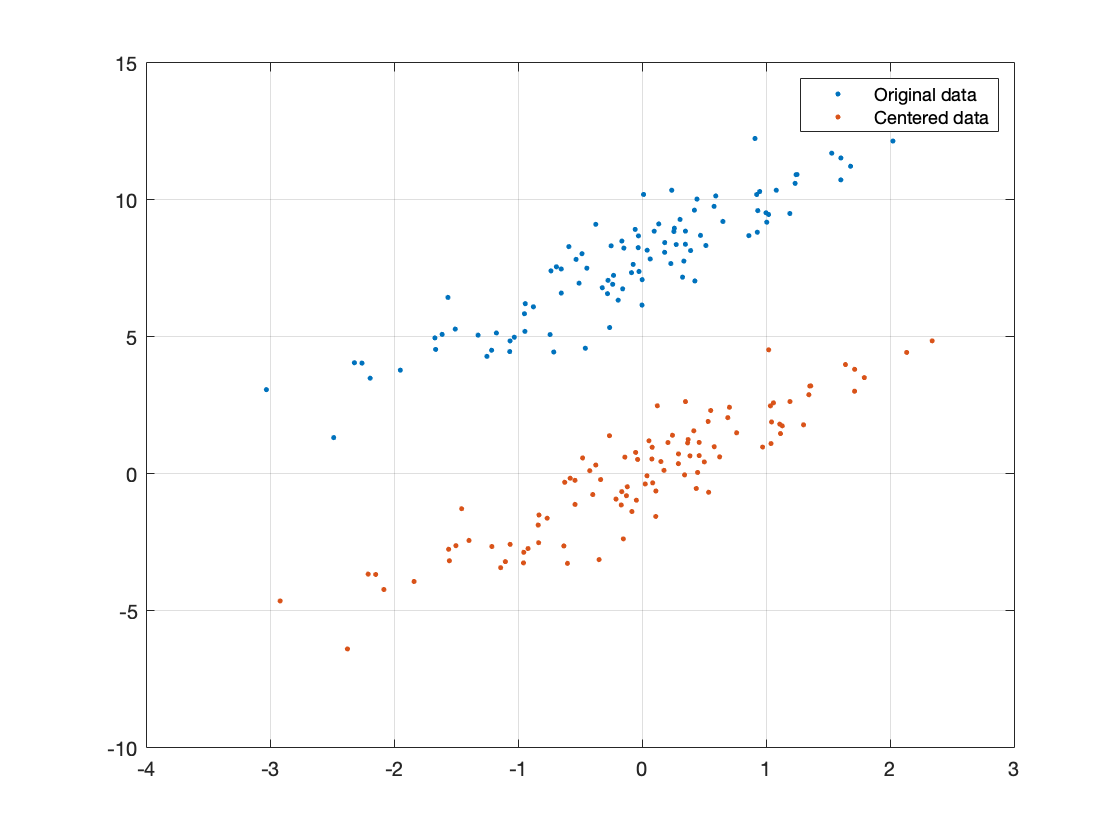

c1 = [2 8];
x1 = randn(1,100);
x2 = polyval(c1,x1)+randn(size(x1));
X = [x1;x2];

[m, n] = size(X);
mx = mean(X,2);
Xo = X - mx*ones(1, n);

figure;

plot(X(1,:),X(2,:),'.')
hold on

plot(Xo(1,:),Xo(2,:),'.')
grid on

legend('Original data', 'Centered data');

Question 5.2

N = length(Xo);
Rx = Xo*Xo'/N ;
[U, D] = eig(Rx);
%diaginal matrix with Rx eignevalues
D

D =     0.1496         0
         0    5.9931


%pxp orthogonal matrix 
%columns are corresponding 
%eigenvectors (matix A)
U

U =    -0.9223    0.3865
    0.3865    0.9223



D=fliplr(flipud(D))

D =     5.9931         0
         0    0.1496


U=fliplr(U)

U =     0.3865   -0.9223
    0.9223    0.3865



U*U'

ans =     1.0000    0.0000
    0.0000    1.0000


U'*U

ans =     1.0000   -0.0000
   -0.0000    1.0000


%it is orthogonal


Eig function organises eigen values in increasing order. If we want to follow a standard procedure we need to reorganise the matrix (flip!!)

Question 5.3

%X=A*Z - EVD

%variation 1
%each eigenvalue_k = var(PC z_k)
A=U

A =     0.3865   -0.9223
    0.9223    0.3865


Z=U'*Xo

Z =     0.7894   -2.8654    2.8042    1.6163    1.3996    0.8190    1.3046   -1.7008    0.7066    0.4755   -0.0519    3.9381   -1.7827    0.1569   -3.2403   -2.7782   -1.2939   -0.6574    4.3189    0.5129   -3.0035    3.4499    3.1879   -0.4746   -2.7751   -0.3162   -0.8987    0.7597   -2.2422    2.3526    0.6010   -3.5938   -2.0423   -2.6642   -0.8453   -0.9254    2.3433   -5.4014   -3.0156    3.4859   -3.3625    2.1549    1.2401    0.9318    0.4621   -1.7311   -0.3253    4.1875    1.1394    0.4778
    0.0120   -0.2044    0.0258    0.2243    0.3198   -0.3356    0.1431    0.1879    0.3520    0.2375    0.4349   -0.2936    0.0823    0.4702   -0.7060   -0.0113   -0.4539   -0.0985    0.0308    0.3648   -0.2249   -0.4130   -0.1229   -0.0700    0.3500    0.2294   -0.3277   -0.1011   -0.7766    0.3850   -0.2932   -0.2701    0.0518   -0.4331    0.0762   -0.1604    0.8483    0.9007   -0.8883   -0.0064   -0.3727   -0.2295    0.0197    0.3018   -0.1243    0.8514   -0.1648   -0.1044    0.2507    0


%A=U*D^(1/2)
%Z=D^(-1/2)*U'*Xo

%Z*Z'/(N-1) is eigenvalues

Question 5.4

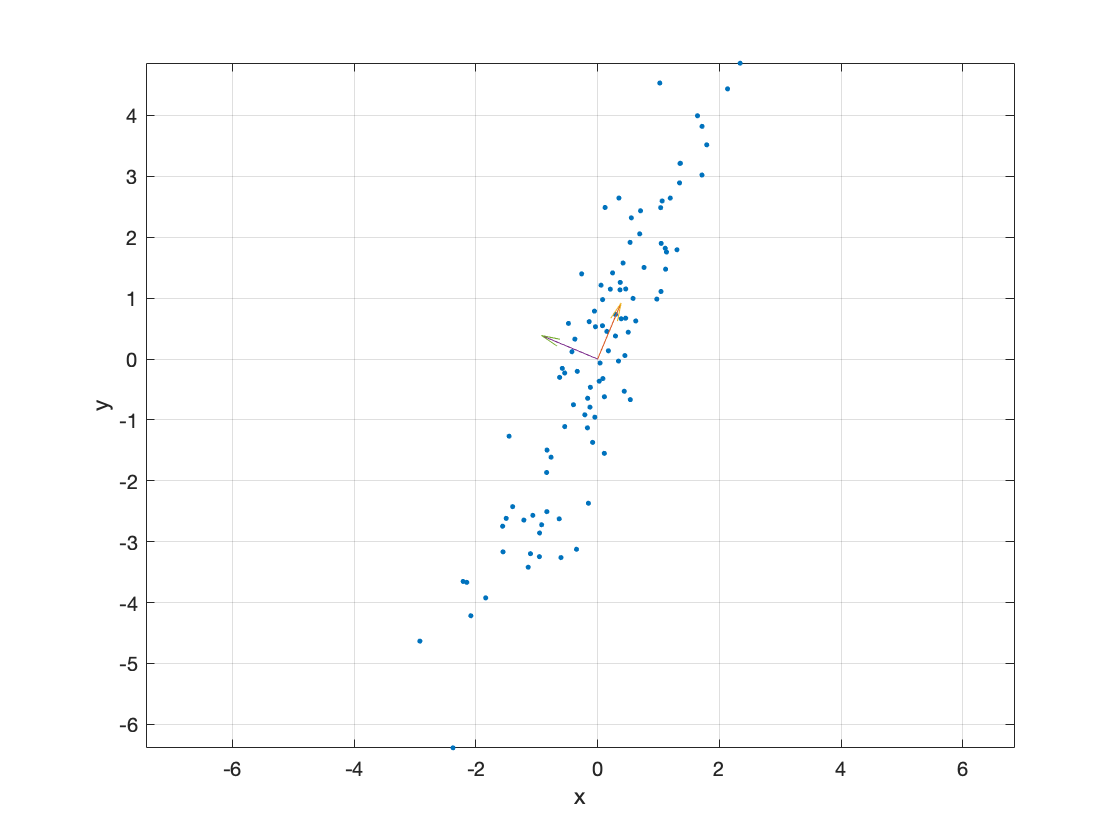

%a)
figure,
plot(Xo(1,:), Xo(2,:),'.')
grid on
hold on
vectarrow([0 0],A(:,1)')
hold on
vectarrow([0 0],A(:,2)')
axis equal 

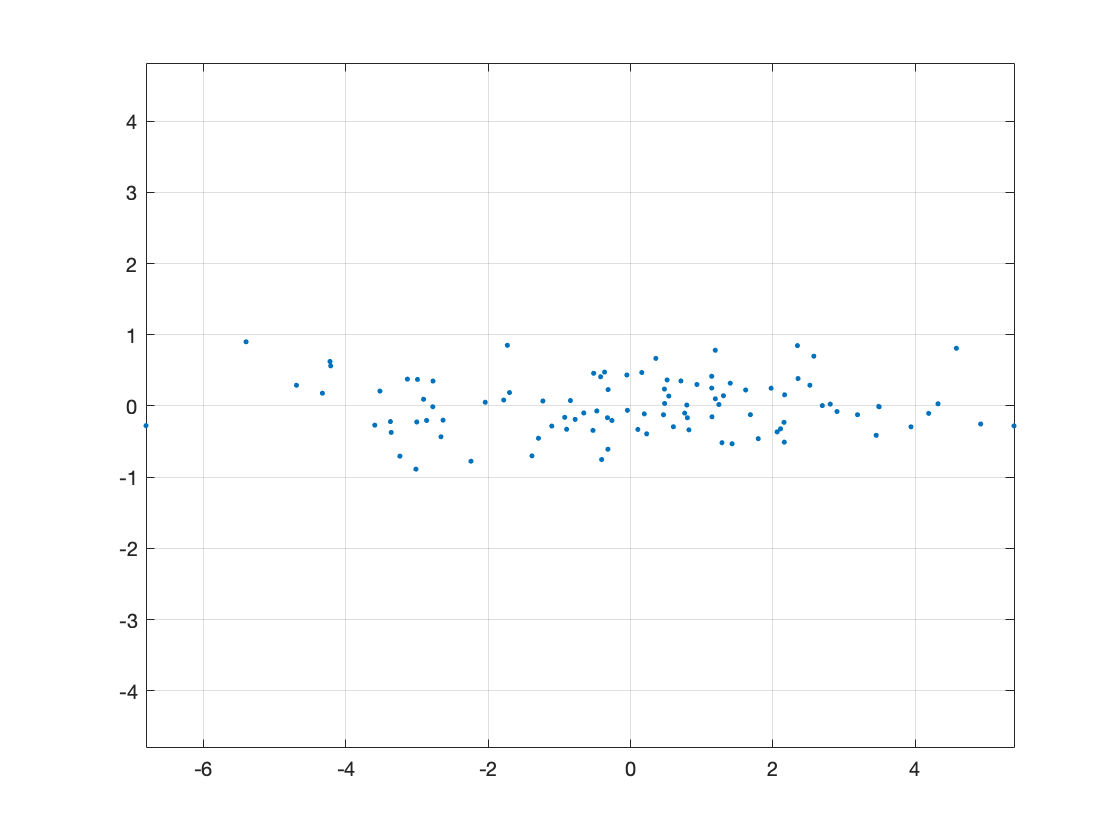


%b)
figure
plot(Z(1,:), Z(2,:),'.')
grid on
axis equal

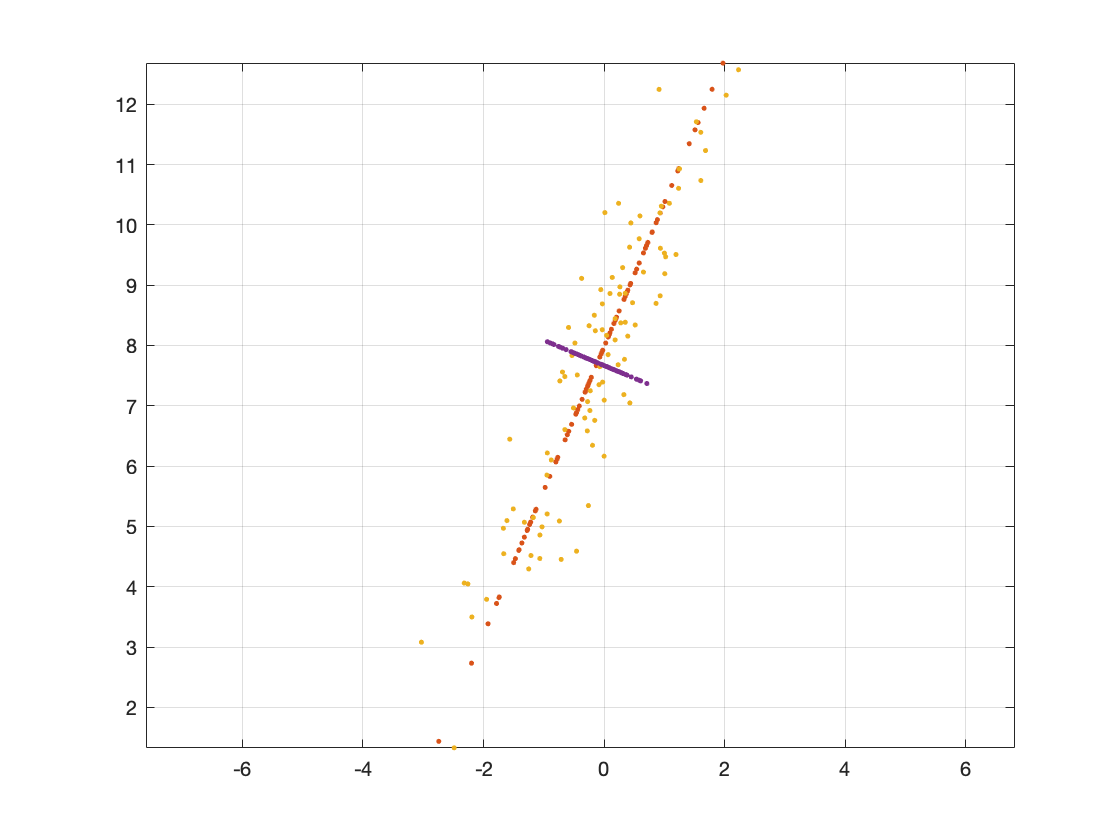


% %variation 2 (WHY?!)
% A=U*D^(1/2)
% Z=D^(-1/2)*U'*Xo
% 
% figure,
% plot(Xo(1,:), Xo(2,:),'.')
% grid on
% hold on
% vectarrow([0 0],A(:,1)')
% hold on
% vectarrow([0 0],A(:,2)')
% axis equal 
% 
% figure
% plot(Z(1,:), Z(2,:),'.')
% grid on

%c)projection of first PC on uncentered data
%using only one dimention (first principal component)

X1=A(:,1)*pinv(A(:,1))*Xo+mx*ones(1,n);

plot(X(1,:),X(2,:),'.')
hold on

plot(X1(1,:),X1(2,:),'.')
grid on 
axis equal

%seconD principal component
X1=A(:,2)*pinv(A(:,2))*Xo+mx*ones(1,n);
plot(X(1,:),X(2,:),'.')
hold on

plot(X1(1,:),X1(2,:),'.')
grid on 
axis equal

%Xo^(1)=A^(1)(A'^(1)A^(1))^(-1)*A'^(1)*Xo=A^(1)A^(1)Xo
%(A'^(1)A^(1)_)A'^(1)_Xo - pseudo inverse

We don't a a direction which deascribes most of the variables

EVD:

Standard definition

1)A is an orthogonal matrix therefore A'A=AA'=I and R_x=D

A=U

Z=U'X

2) Reformulation = PC's with unit variance

 A=U*D^(1/2)

Z=D^(-1/2)*U'*Xo

Assumption: R_z=I (EVD)  PC's have same variances, inofrmation about variance is containted in a transformed matrix A. This is what was set in vectors, which have lenght proportional to variance.

Question 5.5

clear Rx U D Z A

Rx = X*X'/(N-1) ;
[U, D] = eig(Rx);

D=fliplr(flipud(D));
U=fliplr(U);

%3
% A=U
% Z=U'*X

A=U*D^(1/2)

A =     0.1262   -0.9426
    8.0288    0.0148


Z=D^(-1/2)*U'*Xo

Z =     0.4041    0.1087   -0.0853    0.0283    0.2496   -0.2389    0.2229   -0.3261    0.3681    0.0231    0.1456    0.0637   -0.2669   -0.3425   -0.1958   -0.0518    0.0146    0.0590   -0.1844   -0.5399    0.0730    0.2834    0.1684   -0.5618   -0.3961    0.0159    0.0452    0.3348   -0.2267    0.0945    0.1139    0.3958    0.0579   -0.1229    0.2809    0.2937    0.3119   -0.3590   -0.0568   -0.0725   -0.0502   -0.2932    0.5034   -0.0516    0.2967    0.1255    0.1138    0.0713   -0.1272   -0.1902
   -0.9410   -0.6789    0.3283   -0.4215   -0.7617    0.6874   -0.9472    1.7999   -1.8150    0.1974   -0.4248    0.3334   -0.0013    2.0879    1.3910   -0.5921    0.4408   -0.6102    0.2876    1.5174   -0.1881   -0.6904   -0.1930    1.4943    1.2819   -0.1094   -0.3494   -1.4800    0.4844   -0.9121   -0.5665   -1.1281    0.0515    1.5301   -1.1404   -1.8010   -1.0386    0.9972    0.7900   -0.0102    0.3307    0.9994   -1.1537    0.6220   -0.9638    0.3962    0.1651    0.1569    0.4830    0

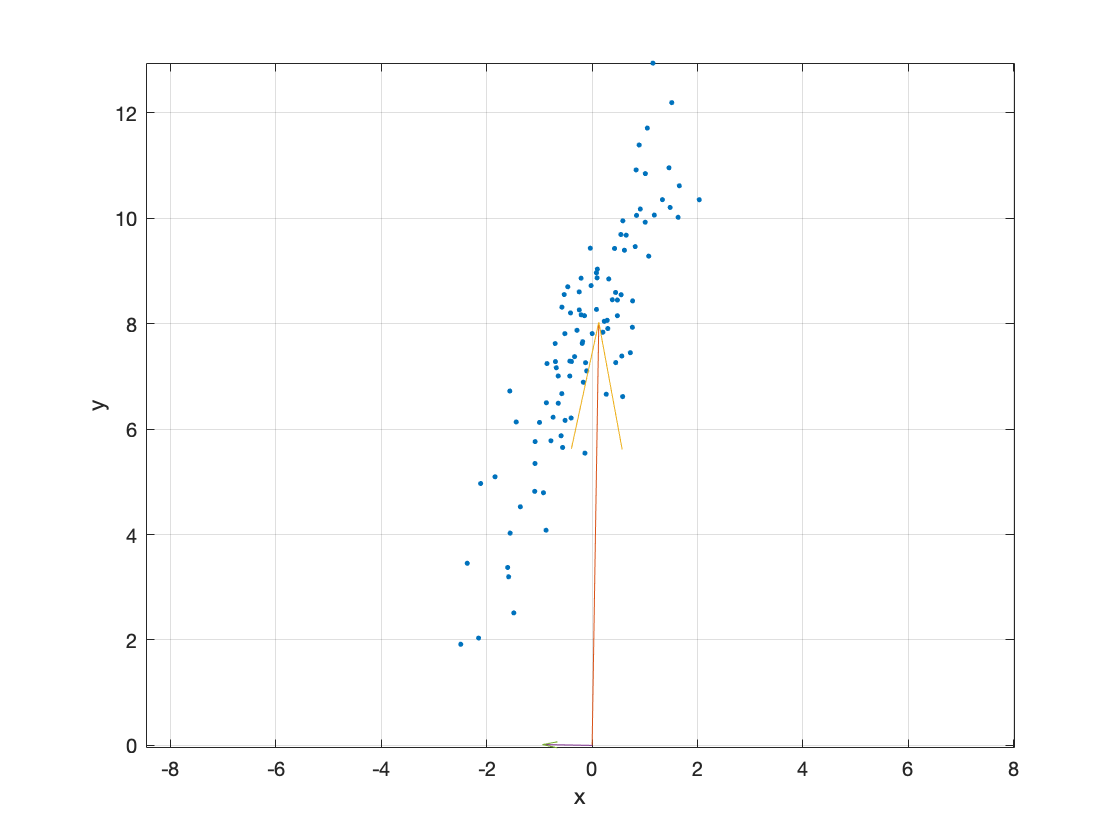


%4
figure,
plot(X(1,:), X(2,:),'.')
grid on
hold on
vectarrow([0 0],A(:,1)')
hold on
vectarrow([0 0],A(:,2)')
axis equal 

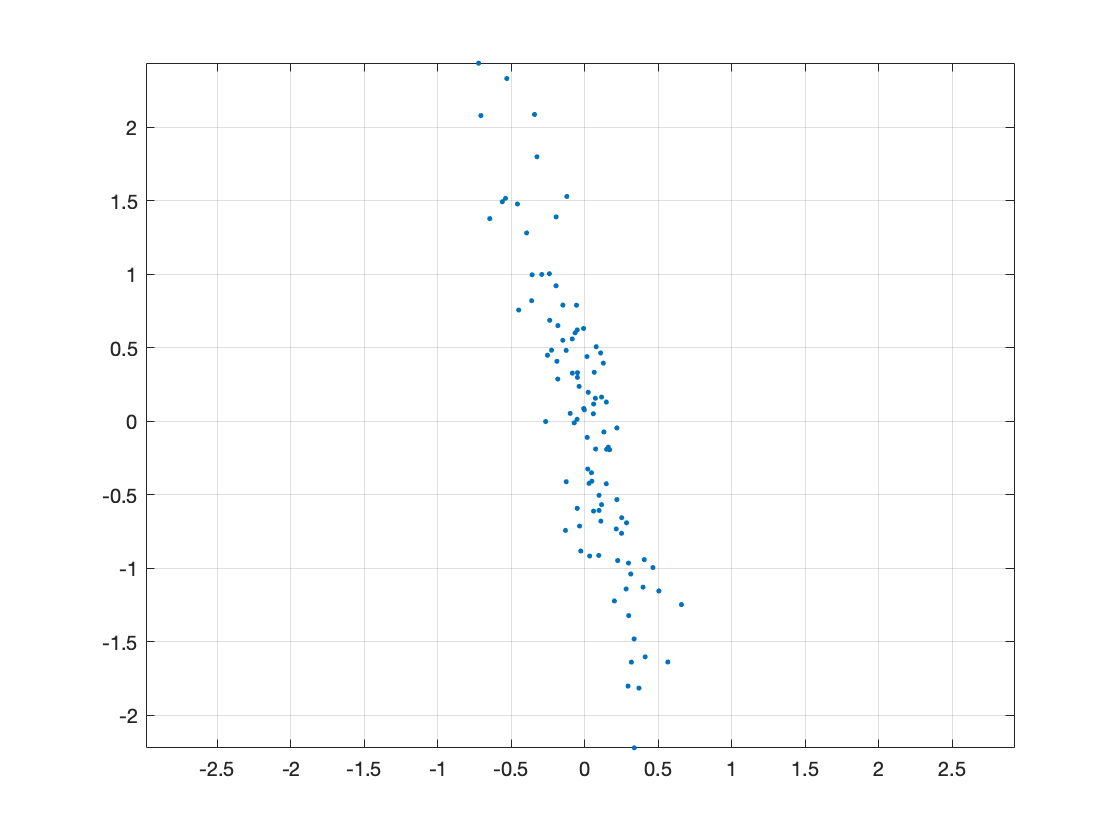


figure
plot(Z(1,:), Z(2,:),'.')
grid on
axis equal

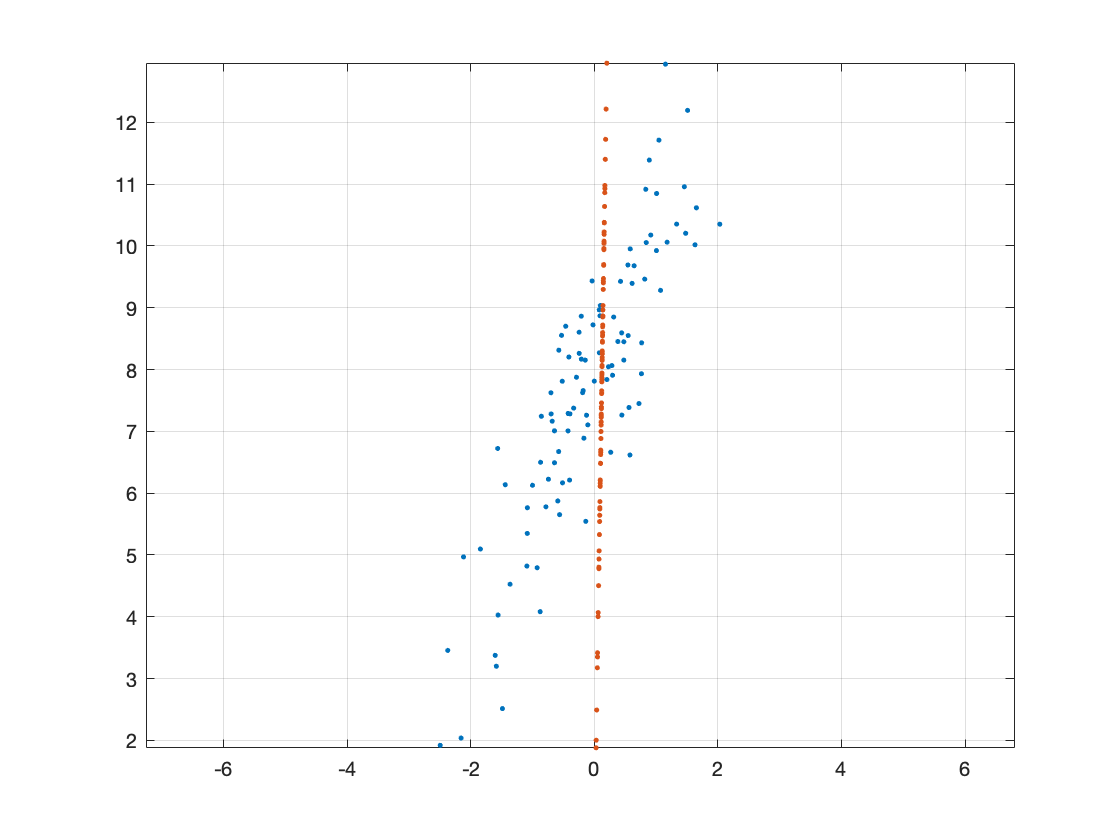


%something that goes 
%into the direction on the centroid
X1=A(:,1)*pinv(A(:,1))*X;
figure
plot(X(1,:),X(2,:),'.')
hold on

plot(X1(1,:),X1(2,:),'.')
grid on 
axis equal


%we need to decide if the centroid is negligible
%do we need to describe th evariance
%or the energy of the data?

% %second principal component
% X1=A(:,2)*pinv(A(:,2))*X;
% plot(X(1,:),X(2,:),'.')
% hold on
% 
% plot(X1(1,:),X1(2,:),'.')
% grid on 
% axis equal


Question 5.6

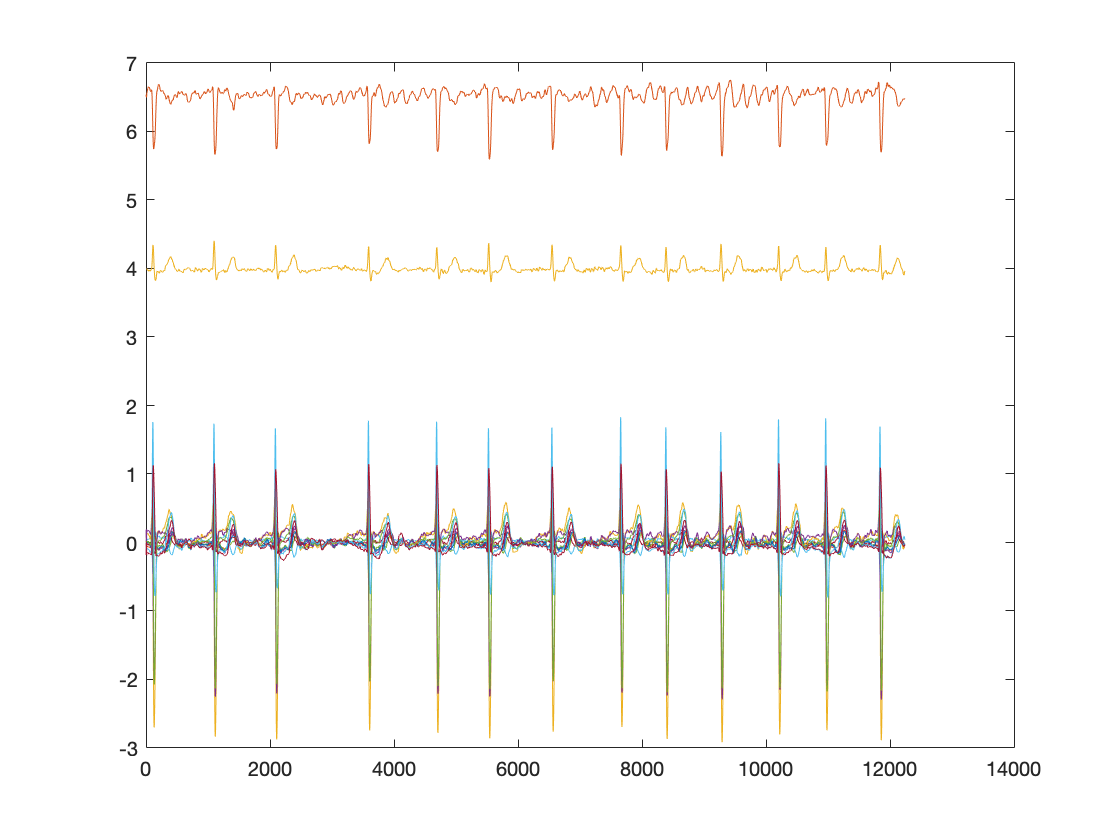

clear
load('data.mat');
size(data);
data=data';
plot(data')

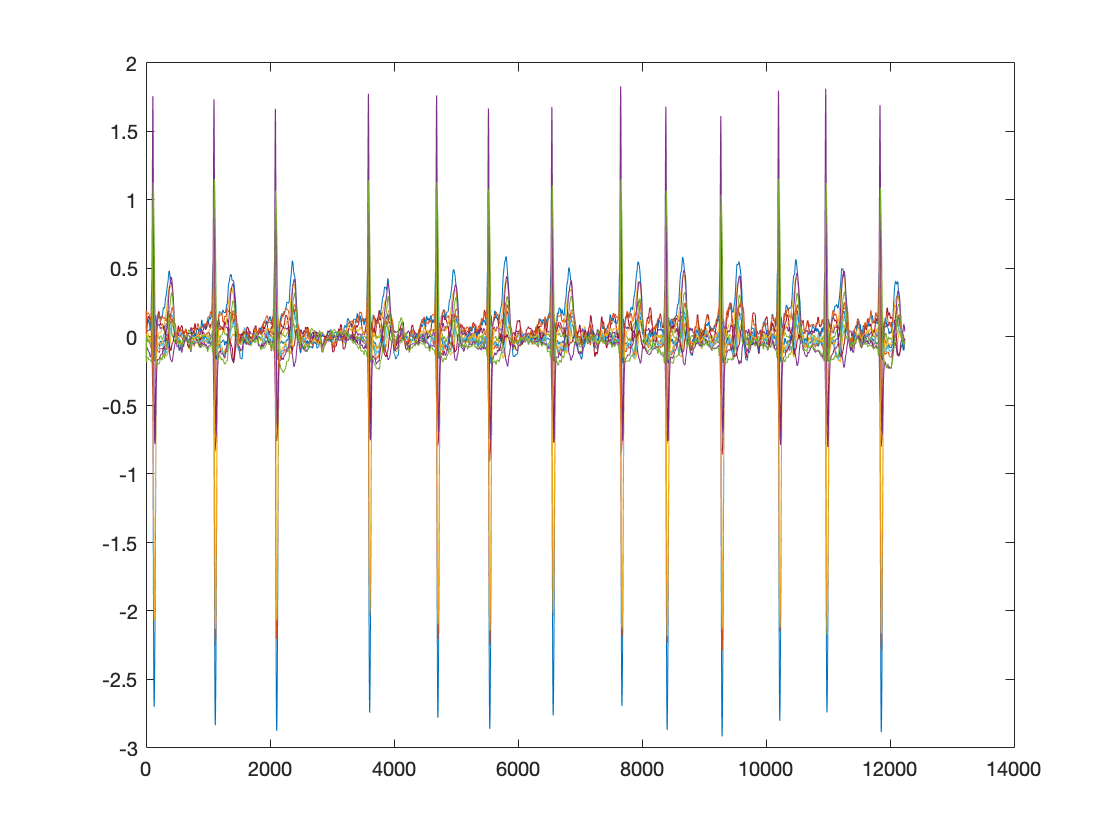


[m, n] = size(data);
mx=mean(data')';
data_centered=data-mx*ones(1,n);

figure,
plot(data_centered')

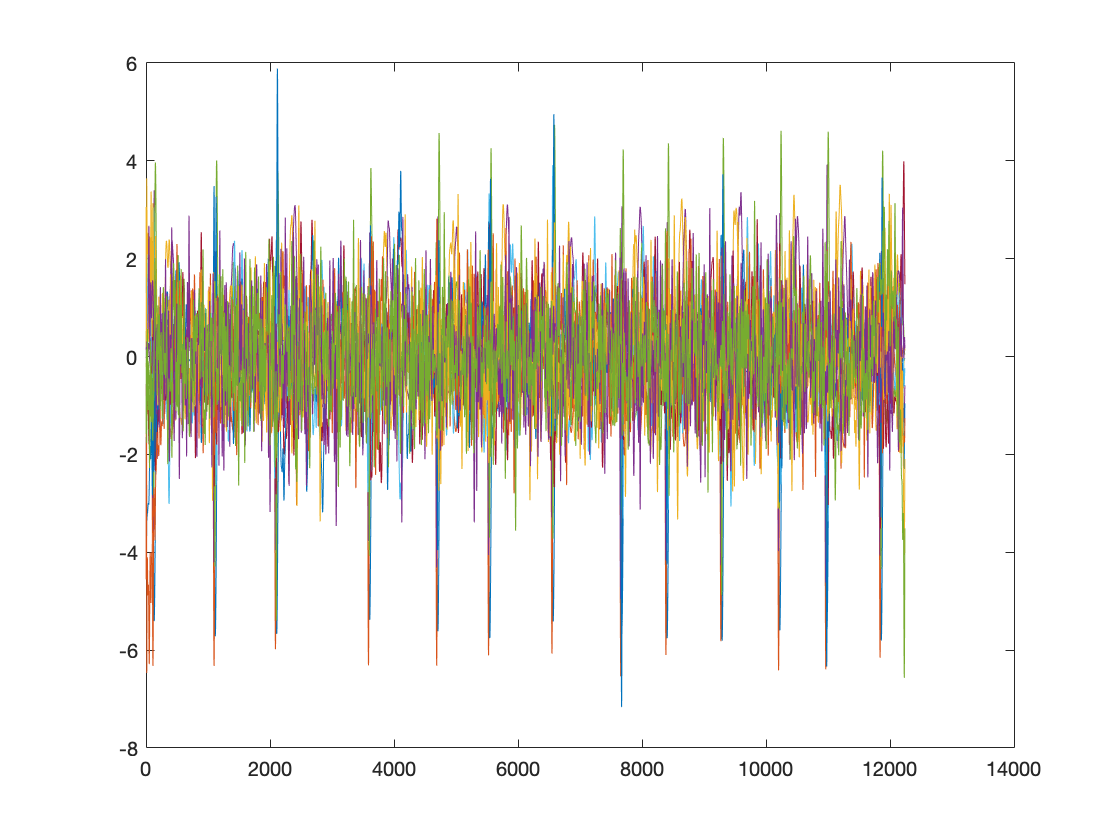

N = length(data);

[U, S, V] = svd(data_centered,'econ');
%X=U*S*V';
%U matrix with orthogonal columns (left singular vectors of X)
%U is orthogonal
%V matrix with orthogonal columns (right singular vectors of X)
%S collects singular values sigma_k of X on diagonal

A=(U*S)/(sqrt(N-1));
Z=sqrt(N-1)*V';
%eigenvalues
D=S.^2;

%plot all th epossible PC
%sharp peaks characterie variance in the data
%PC1-highest variance, 
%other eigenvalues char baseline or noise

figure
plot(Z')

abs(A(:,1))

ans =     0.0112
    0.0251
    0.0364
    0.0063
    0.0242
    0.0305
    0.1410
    0.5114
    0.3946
    0.3514


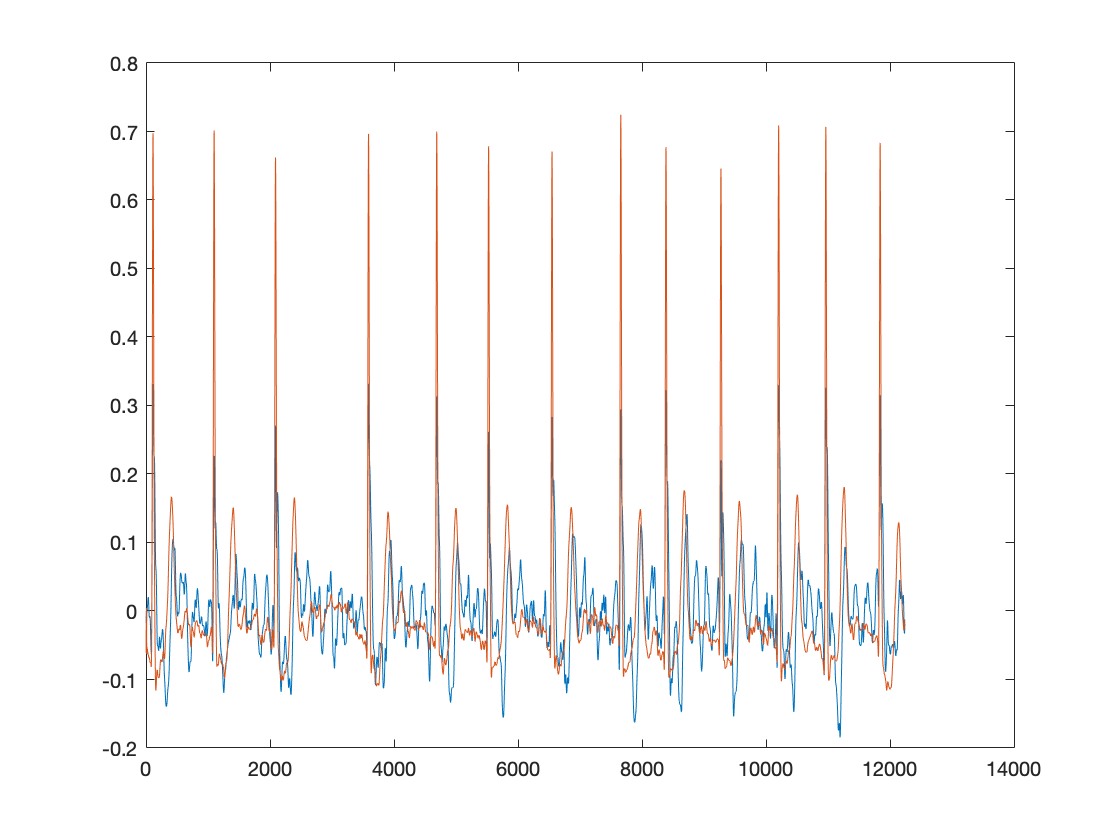

%b)
%blue one is original and 
%red one ir reconstructed one
%just by using first PC (captures most of variation)
%-mostly sharp peaks

%WHY 3?!
%column 1 and column 2 (inf about variance)
PC1=(A(:,[1,2])*pinv(A(:,[1,2]))*data_centered);
plot(data_centered(3,:))
hold on
plot(PC1(2,:))

%c)
%what is the dominant frequency for PC
%beteen 4 and 10
Sdata=fft(Z');
ff=(0:length(Z)-1)*1000/length(Z);
%find dominant peaks in coresponding  frequency
[x,indmax]=max(abs(Sdata));

%3rd, 5th and 6th
ff(indmax)

ans =     1.9608    3.1863    5.8824    1.9608    5.3105    5.3105    1.4706    1.3889    1.0621    1.3072   11.9281    1.3072


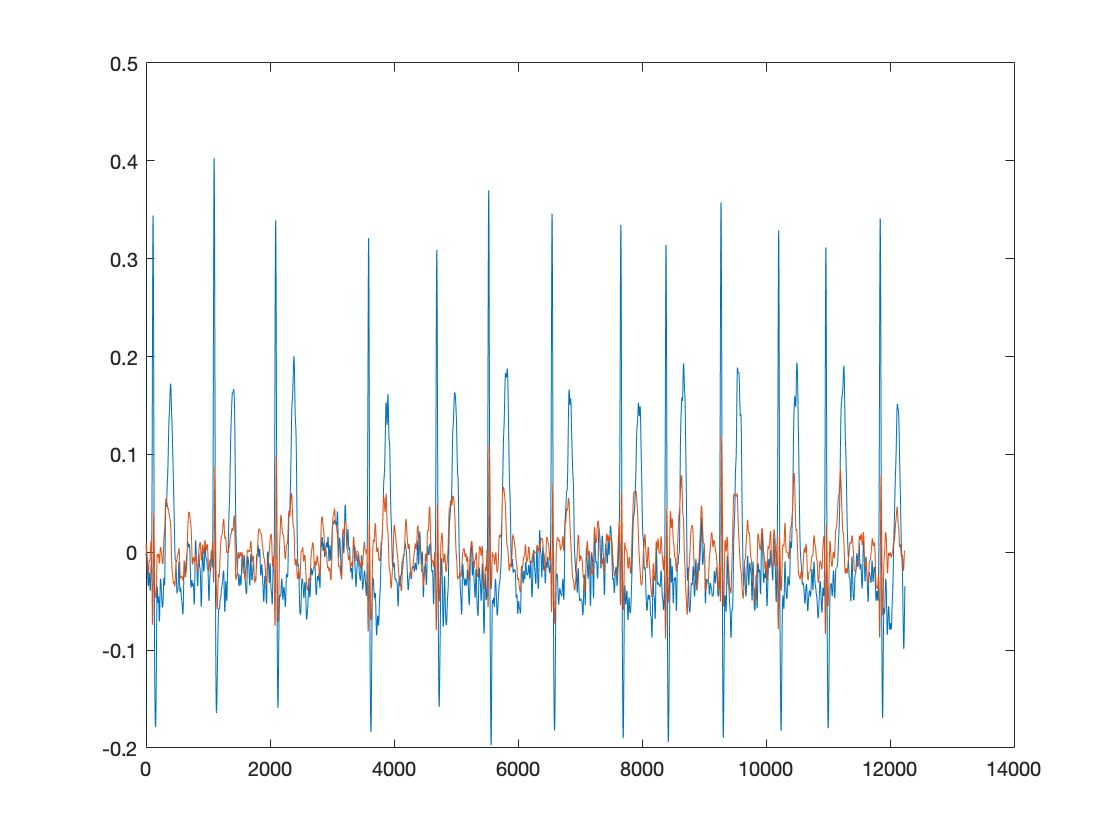


%more automatically
comp_range=find(ff(indmax)>=4 & ff(indmax)<=10);

%if i want to recontruct the original signal
%i can use only 3 components (the ones between 4 and 10 hz)

PC_rec=(A(:,comp_range)*pinv(A(:,comp_range))*data_centered);
%instead of usin one component we're using a set of components
%using a subset of A
%mainly describes a baseline
%data is uncorelated thats why when i retrieve components 
%they might not completely correspond th eoriginal signal
figure;
plot(data_centered(1,:));
hold on
plot(PC_rec(1,:))